clear
clc
close all
addpath('helper_functions')
run("/home/rishabh/vlfeat-0.9.21/toolbox/vl_setup.m");

## Setup

path to the images folder

% path_img_dir = '../data/tracking/valid/img'; TODO: check if it is correct?
path_img_dir = '../data/tracking/validation/img';
% path to object ply file
object_path = '../data/teabox.ply';
% path to results folder
results_path = '../data/tracking/valid/results';

% Read the object's geometry 
% Here vertices correspond to object's corners and faces are triangles
[vertices, faces] = read_ply(object_path);

% Create directory for results
if ~exist(results_path,'dir') 
    mkdir(results_path); 
end

% Load Ground Truth camera poses for the validation sequence
% Camera orientations and locations in the world coordinate system
load('gt_valid.mat')

% TODO: setup camera parameters (camera_params) using cameraParameters()
% A - The camera instrinsic matrix
fx = 2960.37845;
fy = 2960.37845;
cx = 1841.68855;
cy = 1235.23369;
A = [fx, 0, 0; 0, fy, 0; cx, cy, 1];

image_size = [2456, 3680];
camera_params = cameraParameters("IntrinsicMatrix",A, "ImageSize",image_size);

## Get all filenames in images folder

FolderInfo = dir(fullfile(path_img_dir, '*.JPG'));
Filenames = fullfile(path_img_dir, {FolderInfo.name} );
num_files = length(Filenames);

% Place predicted camera orientations and locations in the world coordinate system for all images here
cam_in_world_orientations = zeros(3,3,num_files);
cam_in_world_locations = zeros(1,3,num_files);

## Detect SIFT keypoints in all images

% You will need vl_sift() and vl_ubcmatch() functions
% download vlfeat (http://www.vlfeat.org/download.html) and unzip it somewhere
% Don't forget to add vlfeat folder to MATLAB path

% Place SIFT keypoints and corresponding descriptors for all images here
% keypoints = cell(num_files,1); 
% descriptors = cell(num_files,1); 
% 
% for i=1:length(Filenames)
%     fprintf('Calculating sift features for image: %d \n', i)
%     
% %    TODO: Prepare the image (img) for vl_sift() function
% %  Covert images to grayscale as required by vl_sift()
%     gray_img = rgb2gray(imread(Filenames{i}));
% %   Convert to single precision matrix
%     img = single(gray_img);
%     [keypoints{i}, descriptors{i}] = vl_sift(img) ;
% end
% 
% % Save sift features and descriptors and load them when you rerun the code to save time
% save('sift_descriptors.mat', 'descriptors')
% save('sift_keypoints.mat', 'keypoints')

load('sift_descriptors.mat');
load('sift_keypoints.mat');
% Load the sift model as well
% load('sift_model.mat')

## Initialization: Compute camera pose for the first image

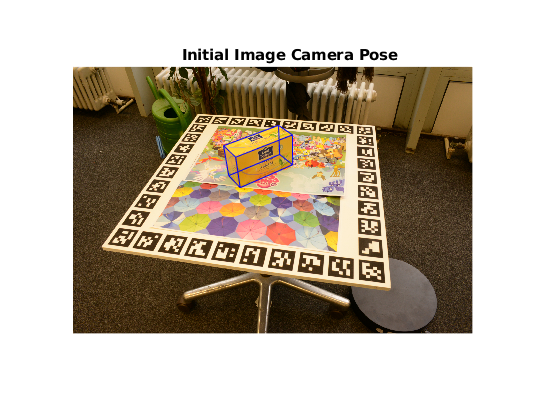

% As the initialization step for tracking
% you need to compute the camera pose for the first image 
% The first image and it's camera pose will be your initial frame 
% and initial camera pose for the tracking process

% Placing matches between new SIFT features and SIFT features from the SIFT
% model here
sift_matches=cell(num_files,1);
initial_image = 1;

% Default threshold for SIFT keypoints matching: 1.5 
% When taking higher value, match is only recognized if similarity is very high
% threshold_ubcmatch = 2.1;

% Match features between SIFT model and SIFT features from new image
% [MATCHES,SCORES] = vl_ubcmatch(descriptors{initial_image}, model.descriptors, threshold_ubcmatch);
% sift_matches{initial_image} = [MATCHES;SCORES];
% 
% save('sift_matches.mat', 'sift_matches');

load("sift_matches.mat")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load('sift_model.mat');
image_points = keypoints{initial_image}(1:2, sift_matches{initial_image}(1, :));
world_points = model.coord3d(sift_matches{initial_image}(2, :), :);
image_points = image_points';
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% You can use estimateWorldCameraPose() function or your own implementation
% of the PnP+RANSAC from previous tasks

% You can get correspondences for PnP+RANSAC either using your SIFT model from the previous tasks
% or by manually annotating corners (e.g. with mark_images() function)

% TODO: Try if manually selecting works better.
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% % Label the coreners using mouse
% imshow('../../Homework1.1/code/vertices.png');
% title('Vertices numbering')
% 
% num_points = 8;
% % labelled_initial_image_points = mark_image(Filenames{1}, num_points);
% % save('labelled_initial_image_points.mat', 'labelled_initial_image_points');
% load('labelled_initial_image_points.mat');
% 
% % Visualise the marked corners
% figure()
% imshow(char(Filenames(1)), 'InitialMagnification', 'fit')
% title(sprintf('Image: %d', i))
% hold on
% for point_idx = 1:8
%     x = labelled_initial_image_points(point_idx,1);
%     y = labelled_initial_image_points(point_idx,2); 
%     if ~isnan(x)
%         plot(x,y,'x', 'LineWidth', 3, 'MarkerSize', 15)
%         text(x,y, char(num2str(point_idx)), 'FontSize',12)
%     end
% end
% 
% % Removing NaN from the labeled_points using rmmissing, which will return
% % labeled points as well as one-hot encoded unlabeled_corners vector
% [image_points, unlabeled_corners] = rmmissing(labelled_initial_image_points(:,:));
% % Get world points only for the corners visible in images,non NaN corners
% world_points = vertices(~unlabeled_corners, :);
% % image_points to homogeneous
% % third_col = ones(size(image_points, 1), 1);
% % image_points = [image_points third_col]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% TODO: Estimate camera position for the first image
% [init_orientation, init_location] = estimateWorldCameraPose(image_points, world_points, camera_params, 'MaxReprojectionError', 2);
[init_orientation, init_location] = estimateWorldCameraPose(image_points, world_points, camera_params, 'MaxReprojectionError', 4, "MaxNumTrials",10000, "Confidence",99.9);

cam_in_world_orientations(:,:, 1) = init_orientation;
cam_in_world_locations(:,:, 1) = init_location;

% Visualise the pose for the initial frame
edges = [[1, 1, 1, 2, 2, 3, 3, 4, 5, 5, 6, 7]
    [2, 4, 5, 3, 6, 4, 7, 8, 6, 8, 7, 8]];
figure()
hold on;
imshow(char(Filenames(1)), 'InitialMagnification', 'fit');
title(sprintf('Initial Image Camera Pose'));
%   Plot bounding box
points = project3d2image(vertices',camera_params, cam_in_world_orientations(:,:,1), cam_in_world_locations(:, :, 1));
for j=1:12
    plot(points(1, edges(:, j)), points(2, edges(:,j)), 'color', 'b');
end
hold off;

## IRLS nonlinear optimisation

% Now you need to implement the method of iteratively reweighted least squares (IRLS)
% to optimise reprojection error between consecutive image frames

% Method steps:
% 1) Back-project SIFT keypoints from the initial frame (image i) to the object using the
% initial camera pose and the 3D ray intersection code from the task 1. 
% This will give you 3D coordinates (in the world coordinate system) of the
% SIFT keypoints from the initial frame (image i) that correspond to the object
% 2) Find matches between descriptors of back-projected SIFT keypoints from the initial frame (image i) and the
% SIFT keypoints from the subsequent frame (image i+1) using vl_ubcmatch() from VLFeat library
% 3) Project back-projected SIFT keypoints onto the subsequent frame (image i+1) using 3D coordinates from the
% step 1 and the initial camera pose 
% 4) Compute the reprojection error between 2D points of SIFT
% matches for the subsequent frame (image i+1) and 2D points of projected matches
% from step 3
% 5) Implement IRLS: for each IRLS iteration compute Jacobian of the reprojection error with respect to the pose
% parameters and update the camera pose for the subsequent frame (image i+1)
% 6) Now the subsequent frame (image i+1) becomes the initial frame for the
% next subsequent frame (image i+2) and the method continues until camera poses for all
% images are estimated

% We suggest you to validate the correctness of the Jacobian implementation
% either using Symbolic toolbox or finite differences approach

% TODO: Implement IRLS method for the reprojection error optimisation
% You can start with these parameters to debug your solution 
% but you should also experiment with their different values
threshold_irls = 0.000001;%0.005; % update threshold for IRLS
N = 200; % number of iterations -- TODO: increase it 100 or 200
threshold_ubcmatch = 6;%2.0;%4;%5;%6; % matching threshold for vl_ubcmatch()
% last time we used 2.0. Very much strict this threshold of 6

% Some initial setup

% Store all model backprojection here
per_image_model = cell(num_files, 1); %unused

first_vertex_idx = faces(:, 1) + 1; % get the list of first vertex idx for all faces, +1 to get into matlab indexing
second_vertex_idx = faces(:, 2) + 1; % get the list of second vertex idx for all faces, +1 to get into matlab indexing
third_vertex_idx = faces(:, 3) + 1; % get the list of third vertex idx for all faces, +1 to get into matlab indexing
% Vertices list for TriangleRayIntersection()
first_vertices = vertices(first_vertex_idx, :);
second_vertices = vertices(second_vertex_idx, :);
third_vertices = vertices(third_vertex_idx, :);

for i = 1:(num_files - 1) % -1 necessary for i, i+1 behaviour
    fprintf("Iteration %d\n", i);
    %% 1. Back-Project initial frame for 3D world cordinates using TriangleRayIntersection()
    
    % Total number of sift keypoints for the current image
    size_total_sift_points = size(keypoints{i}, 2);
    % Placing model's SIFT keypoints coordinates and descriptors here
    model.coord3d = zeros(size_total_sift_points, 3);
    model.descriptors = zeros(128, size_total_sift_points, 'uint8');
    % Current point index used for saving the points in model world
    % cordinates system
    point_index = 0;
    point = ones(3,1); % point corresponds to m in the equation r(m) -- point = [x, y, 1]'
    
    % Find the optical center of the camera
    P = camera_params.IntrinsicMatrix.'*[cam_in_world_orientations(:,:,i) -cam_in_world_orientations(:,:,i)*cam_in_world_locations(:,:,i).'];
    Q = P(:,1:3);
    q = P(:,4);
    orig = -inv(Q)*q; % this corresponds to C
    
    % Randomly select a number of SIFT keypoints -- Can skip randomness as
    % we are using all the points anyways
    perm = randperm(size(keypoints{i},2));
    sel = perm(1:size_total_sift_points);
    
    for j=1:size_total_sift_points
        point(1:2) = keypoints{i}(1:2, j); % or just j instead of sel(j) | removed sej(j) as sometimes world_points are zero
        % Ray direction
        r = Q\point;
        r = r/norm(r); % Try skipping this step?
        
        % call to TriangleRayIntersection()
        [intersect_arr, distance_ray_origin_intersect_pt, u_b, v_b, x_coor] = TriangleRayIntersection(orig', r', first_vertices, ...
            second_vertices, third_vertices, 'planeType', 'one sided'); % ignores occluded faces + think about inclusive border case
        if any(size(find(intersect_arr)) > 1)
            throw MException("Double Intersection!")
        end
        
        if any(intersect_arr)
            point_index = point_index + 1;
            intersection_idx = find(intersect_arr);
            world_point_idx = x_coor(intersection_idx, :);
            model.coord3d(point_index, :) = world_point_idx; % if more than one intersection then world_point_idx(1,:)-- border inclusive
            model.descriptors(:, point_index) = descriptors{i}(:, j); % or only j instead sel(j)| removed sej(j) as sometimes world_points are zero
        end
    end
    
    %% 2. Between i and i+1 finding SIFT matches
    
    % Covert images to grayscale as required by vl_sift()
    gray_img = rgb2gray(imread(Filenames{i+1}));
    % Convert to single precision matrix
    img = single(gray_img);
    
    % Match features between SIFT model and SIFT features from new image
    [MATCHES,SCORES] = vl_ubcmatch(descriptors{i+1}, model.descriptors, threshold_ubcmatch);
    sift_matches{i+1} = [MATCHES;SCORES];
    size(sift_matches{i+1})
    index_keypoints_image = sift_matches{i+1}(1, :);
    index_keypoints_model = sift_matches{i+1}(2, :);
    image_model_match_scores = sift_matches{i+1}(3, :);
    fprintf("Matching done for model and image %d\n", i+1);
    % TODO : i+1 and model or i and i+1, vl_ubcmatch()?
    % Find matches between descriptors of back-projected SIFT keypoints from the initial frame (image i) and the
    % SIFT keypoints from the subsequent frame (image i+1) using vl_ubcmatch() from VLFeat library
    % back-projected SIFT keypoints descriptors from the initial frame (image i) = model.descriptors 
    
    %% 3. Projecting 3D world points to image i+1
    
    % using notations from the lecture slides (for most of the stuff)
    
    % 3D model point camera i
    M = model.coord3d(index_keypoints_model, :);
    % 2D image points camera i+1; taking x and y cordinates from the
    % stored keypoints 
    m = keypoints{i+1}(1:2, index_keypoints_image);
    
    % Camera orientation and location in world wrt to previous image is
    % always known
    % Convert camera pose to extrinsics
    [rotationMatrix, translationVector] = cameraPoseToExtrinsics(cam_in_world_orientations(:, :, i), cam_in_world_locations(:, :, i));
    
    % SO(3) to so(3)
    rotationVextor = rotationMatrixToVector(rotationMatrix);
    init_parameters = [rotationVextor' ; translationVector'];
    
    % Algorithm 1 IRLS: Iteratively re-weighted least squares
    theta = init_parameters;
    t = 0;
    lamda = 0.001;
    u = threshold_irls + 1;
    % Jacobian -- TODO: compare with internal symbolic jacobian
    jacobian_m = jacobian_matrix(rotationMatrix, translationVector, M, camera_params);
    
    while (t < N && u > threshold_irls)
        % Evaluate energy
        [E, W, e] = calculate_energy(camera_params, rotationMatrix, translationVector, M, m);
        
        % Compute the update
        delta = -inv(jacobian_m'*W*jacobian_m + lamda*eye(6))*(jacobian_m'*W*e);
        % Preparing for calculation of E(thetha + delta)
        theta_new = theta + delta;
        rotationMatrix_new = rotationVectorToMatrix(theta_new(1:3));
        translationVector_new = theta_new(4:6)';
        % E(thetha + delta)
        [E_new, W_new, e_new] = calculate_energy(camera_params, rotationMatrix_new, translationVector_new, M, m);
        
        if E_new > E
            lamda = lamda*10;
        else
            lamda = lamda/10;
            theta = theta_new;
            rotationMatrix = rotationMatrix_new;
            translationVector = translationVector_new;
            jacobian_m = jacobian_matrix(rotationMatrix, translationVector, M, camera_params);
        end
        u = norm(delta);
        t = t+1;
    end
    % Update camera pose
    [cam_in_world_orientations(:, :, i+1), cam_in_world_locations(:, :, i+1)] = extrinsicsToCameraPose(rotationMatrix, translationVector);
end

Iteration 1


ans =      3   372


Matching done for model and image 2


Iteration 2


ans =      3   374


Matching done for model and image 3


Iteration 3


ans =      3   365


Matching done for model and image 4


Iteration 4


ans =      3   308


Matching done for model and image 5


Iteration 5


ans =      3   280


Matching done for model and image 6


Iteration 6


ans =      3   125


Matching done for model and image 7


Iteration 7


ans =      3   118


Matching done for model and image 8


Iteration 8


ans =      3   337


Matching done for model and image 9


Iteration 9


ans =      3   328


Matching done for model and image 10


Iteration 10


ans =      3   239


Matching done for model and image 11


Iteration 11


ans =      3   245


Matching done for model and image 12


Iteration 12


ans =      3   259


Matching done for model and image 13


Iteration 13


ans =      3   247


Matching done for model and image 14


Iteration 14


ans =      3   280


Matching done for model and image 15


Iteration 15


ans =      3   258


Matching done for model and image 16


Iteration 16


ans =      3   277


Matching done for model and image 17


Iteration 17


ans =      3   256


Matching done for model and image 18


Iteration 18


ans =      3   265


Matching done for model and image 19


Iteration 19


ans =      3   287


Matching done for model and image 20


Iteration 20


ans =      3   268


Matching done for model and image 21


Iteration 21


ans =      3   326


Matching done for model and image 22


Iteration 22


ans =      3   291


Matching done for model and image 23


Iteration 23


ans =      3   339


Matching done for model and image 24


Iteration 24


ans =      3   298


Matching done for model and image 25


## Plot camera trajectory in 3D world CS + cameras

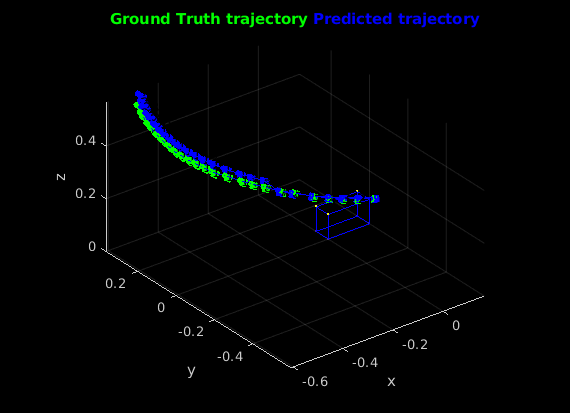

figure()
% Predicted trajectory
visualise_trajectory(vertices, edges, cam_in_world_orientations, cam_in_world_locations, 'Color', 'b');
hold on;
% Ground Truth trajectory
visualise_trajectory(vertices, edges, gt_valid.orientations, gt_valid.locations, 'Color', 'g');
hold off;
title('\color{green}Ground Truth trajectory \color{blue}Predicted trajectory')

## Visualize bounding boxes

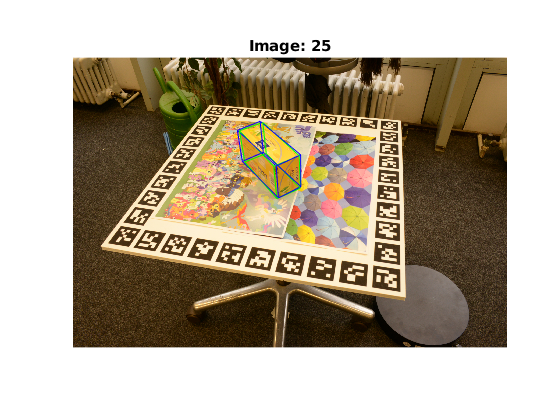

figure()
for i=1:num_files
    
    imshow(char(Filenames(i)), 'InitialMagnification', 'fit');
    title(sprintf('Image: %d', i))
    hold on
    % Ground Truth Bounding Boxes
    points_gt = project3d2image(vertices',camera_params, gt_valid.orientations(:,:,i), gt_valid.locations(:, :, i));
    % Predicted Bounding Boxes
    points_pred = project3d2image(vertices',camera_params, cam_in_world_orientations(:,:,i), cam_in_world_locations(:, :, i));
    for j=1:12
        plot(points_gt(1, edges(:, j)), points_gt(2, edges(:,j)), 'color', 'g');
        plot(points_pred(1, edges(:, j)), points_pred(2, edges(:,j)), 'color', 'b');
    end
    hold off;
    
    filename = fullfile(results_path, strcat('image', num2str(i), '.png'));
    saveas(gcf, filename)
end

save('cam_in_world_orientations.mat', 'cam_in_world_orientations');
save('cam_in_world_locations.mat', 'cam_in_world_locations');

## Bonus part

% Save estimated camera poses for the validation sequence using Vision TUM trajectory file
% format: https://vision.in.tum.de/data/datasets/rgbd-dataset/file_formats
% Then estimate Absolute Trajectory Error (ATE) and Relative Pose Error for
% the validation sequence using python tools from: https://vision.in.tum.de/data/datasets/rgbd-dataset/tools
% In this task you should implement you own function to convert rotation matrix to quaternion

% Save estimated camera poses for the test sequence using Vision TUM 
% trajectory file format

% Attach the file with estimated camera poses for the test sequence to your code submission
% If your code and results are good you will get a bonus for this exercise
% We are expecting the mean absolute translational error (from ATE) to be
% approximately less than 1cm

% TODO: Estimate ATE and RPE for validation and test sequences